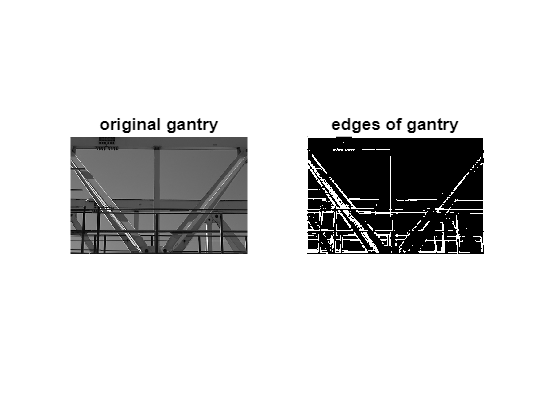

img=imread("gantrycrane.png");
img=im2gray(img);
hor_mask = [-1 -1 -1; 2 2 2; -1 -1 -1]; 
pos_mask = [2 -1 -1; -1 2 -1; -1 -1 2]; 
ver_mask = [-1 2 -1; -1 2 -1; -1 2 -1]; 
neg_mask = [-1 -1 2; -1 2 -1; 2 -1 -1]; 
hor_img=conv2(img,hor_mask);
pos_img=conv2(img,pos_mask);
ver_img=conv2(img,ver_mask);
neg_img=conv2(img,neg_mask);
result=sqrt(hor_img.^2 + pos_img.^2 + ver_img.^2+ neg_img.^2);
for i=1:1:266
    for j=1:1:402
        if (result(i,j)>150)
            result(i,j)=255;
        else
            result(i,j)=0;
        end

    end
end
figure
subplot(1,2,1), imshow(img), title("original gantry");
subplot(1,2,2), imshow(result), title("edges of gantry");